# Analisis de tendencia


ae = exist("arr_ndvi","var");
if ae == 0  %si no existe, cargar la infromación
    new_cargar_informacion
end

## Filtrar información

% Declaraciones
% Los años que se desean consultar
meses = [4,9];
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
arr_prom_septiembre =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));
arr_prom_abril =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));

arr_max_septiembre =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));
arr_max_abril =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));

arr_min_septiembre =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));
arr_min_abril =zeros(ndvi_tam(1),ndvi_tam(2), length(anios));


arr_ndvi_lf(arr_ndvi_lf<=0.001)=nan; 
   
bp=waitbar(0,'Filtrando información'); 

for y= 1:length(anios)
    waitbar(y/length(anios),bp);

        % Abril 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 4  ); % Abril
        if( ~isempty (tmp))
            % promedio
            arr_prom_abril(:,:,y) = m_mean_3dpp(arr_ndvi_lf (:,:,tmp));            
            % maximo
            arr_max_abril(:,:,y) = m_max_3dpp(arr_ndvi_lf (:,:,tmp));
            % minimo
            arr_min_abril(:,:,y) = m_min_3dpp(arr_ndvi_lf (:,:,tmp));

        end
   
        % Septiembre 
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == 9  ); 
        if( ~isempty (tmp))
            % promedio
            arr_prom_septiembre(:,:,y) = m_mean_3dpp(arr_ndvi_lf (:,:,tmp));
            % maximo
            arr_max_septiembre(:,:,y) = m_max_3dpp(arr_ndvi_lf (:,:,tmp));
            % minimo
            arr_min_septiembre(:,:,y) = m_min_3dpp(arr_ndvi_lf (:,:,tmp));
             
        end
                 
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 


### 4.- Usar los datos obtenidos 

Mostrar mapas de septiembre

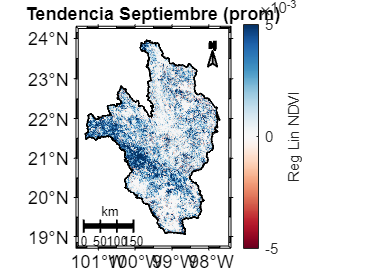

inter_color = [-0.005 0.005];

[~,ma1,~] = m_reglin_3dpp(arr_prom_septiembre);

ma_up = ma1;
ma_down = ma1;

ma_up(ma1<=0)=0;
ma_down(ma1>0)=0;

figure;
 ma_up(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma_up,"Tendencia Septiembre (prom)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_prom_sept_up.png",'Resolution',300) 

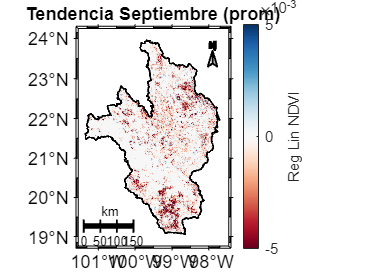


figure;
 ma_down(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma_down,"Tendencia Septiembre (prom)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_prom_sept_down.png",'Resolution',300) 

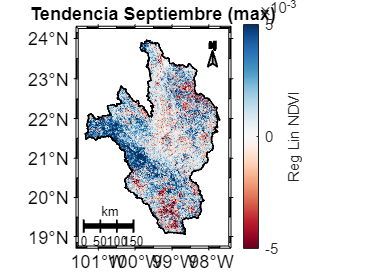



[~,ma1,~] = m_reglin_3dpp(arr_max_septiembre);

figure;
 ma1(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Tendencia Septiembre (max)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_max_sept.png",'Resolution',300) 

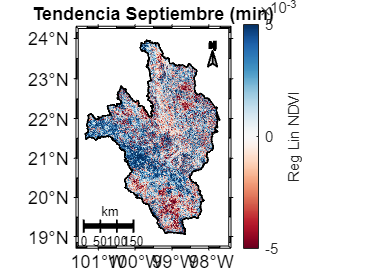


 [~,ma1,~] = m_reglin_3dpp(arr_min_septiembre);

figure;
 ma1(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Tendencia Septiembre (min)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_min_sept.png",'Resolution',300) 

Mostrar mapas de abril 

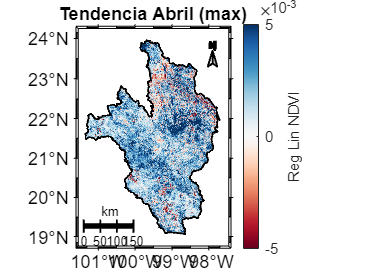


 [~,ma1,~] = m_reglin_3dpp(arr_max_abril);
figure;
 ma1(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Tendencia Abril (max)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_max_abril.png",'Resolution',300) 

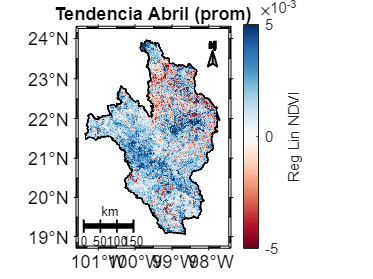


 [~,ma1,~] = m_reglin_3dpp(arr_prom_abril);
figure;
 ma1(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Tendencia Abril (prom)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_prom_abril.png",'Resolution',300) 

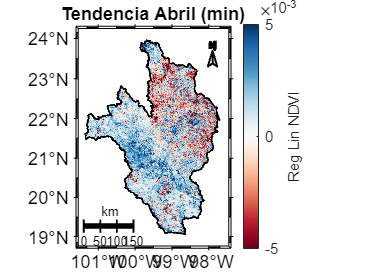



 [ma0,ma1,yaj] = m_reglin_3dpp(arr_min_abril);
 figure;
 ma1(area_estudio==false)=nan;
 m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ma1,"Tendencia Abril (min)",inter_color, flipud(m_colmap('diverging',256)) ,"Reg Lin NDVI");
 m_dibujar_kml(dir_data,"RH26",1,"k","");
 %m_dibujar_otras_areas(dir_data);

 ax = gca;
 exportgraphics(ax,"img/new_reg_lin_min_abril.png",'Resolution',300) 